load("sysIDdata.mat");

%sets the sampling frequency
samplingFrequency = 8000;

%plays the noisy audio
noisePlayer = audioplayer(p,samplingFrequency);
%playblocking(noisePlayer);

%plays the z audio
zPlayer = audioplayer(z, samplingFrequency);
%playblocking(zPlayer);


%writes z and p, and h true out to csv files
csvwrite("z_audio.csv", z)
csvwrite("p_audio.csv", p)
csvwrite("h_true.csv", h_true)



%sets the length of our filter to 120 and initializes
%all the taps to start at zero.
M = 101;
h_initial = zeros([M 1]);


%sets the mu constant
mu = 0.001;

%runs the adaptive filter method
[y,e,h] = lms(p,z,mu,h_initial);

a =     0.7885
    1.1287
   -0.8881
    1.2248
   -0.3331
   -1.0416
    1.0181
    0.4829
    1.7530
    1.2748


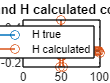


    

%does a stem plot of the h_true coefficients and
%the h coefficients
stem(h_true);
hold on;
title("H true and H calculated coefficients");
stem(h);
legend('H true', 'H calculated');
hold off;

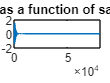



%plots the error
plot(e);
title("Error as a function of samples");

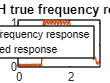


%plays the y (output) audio
outputPlayer = audioplayer(y, samplingFrequency);
%playblocking(outputPlayer);

%plots the frequency response of h_true and h
[h_true_response, omega_0] = freqz(h_true,1);
[h_response, omega] = freqz(h,1);
plot(omega_0, abs(h_true_response));
hold on;
title("H and H true frequency response");
plot(omega, abs(h_response));
legend("H true frequency response", "H created response");
hold off;



%plots the frequency response of h
